clc; clear; close all;

%% ========================================================================
% SYSTEM CONFIGURATION
%% ========================================================================
M = 64; % Subcarriers
N = 16; % Symbols
cpSize = 16;          
constOrder = 2; % BPSK
numFrames = 100;         
% Adjusted range and step to ensure -10, -5, 0, 5, 10, 15, 20 are included
snrRange = -10:5:20;    
dopplerRange = 0:100:1500; 
fs = 15e3 * M;    
numBits = M * N * log2(constOrder);

channelNames = {'AWGN', 'Rayleigh', 'Rician', 'Nakagami-m', 'Weibull', 'Suzuki', 'Hoyt'};
numCh = length(channelNames);

fprintf('Starting Simulation: SNR points at -10, -5, 0, 5, 10, 15, 20...\n');

Starting Simulation: SNR points at -10, -5, 0, 5, 10, 15, 20...


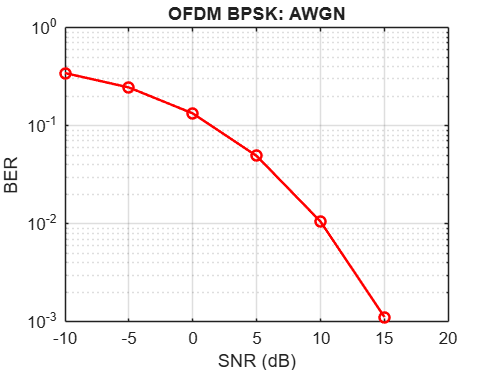

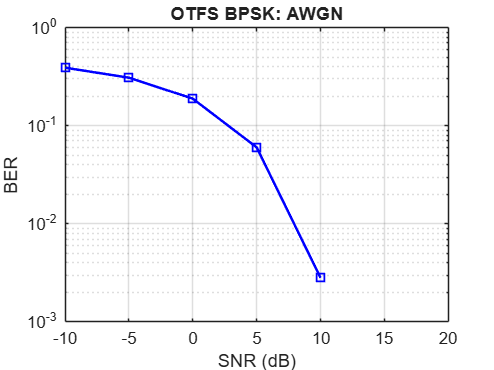

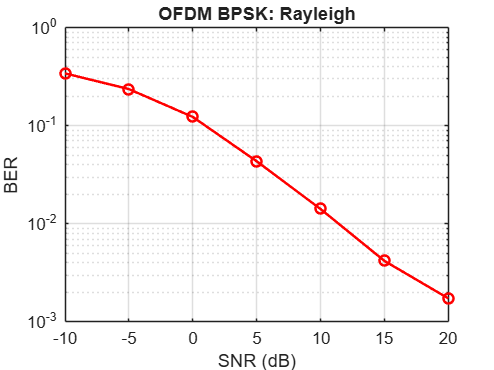

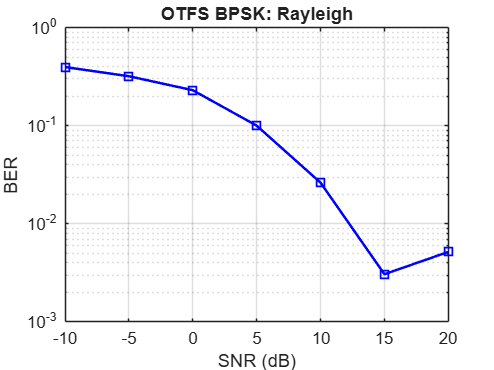

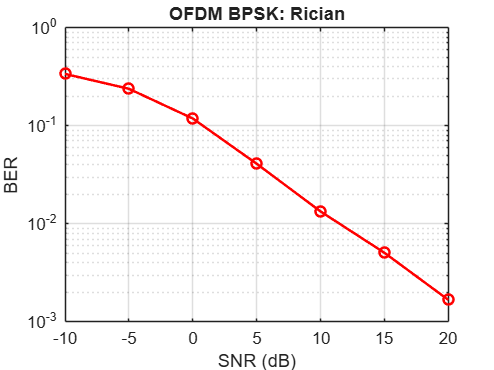

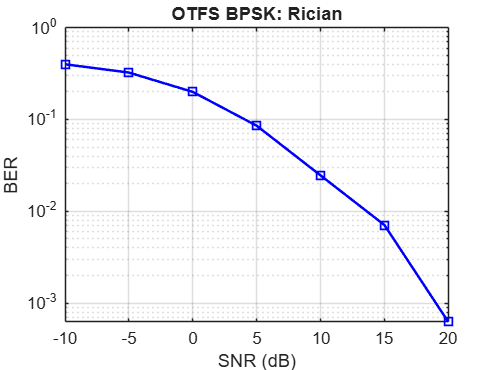

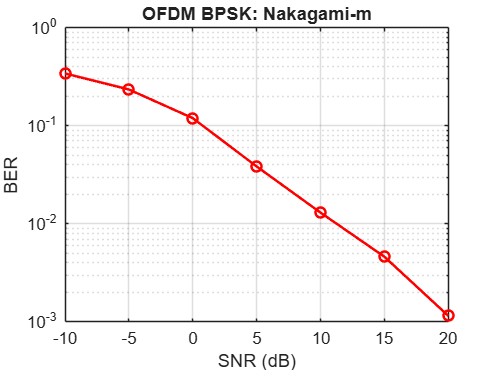

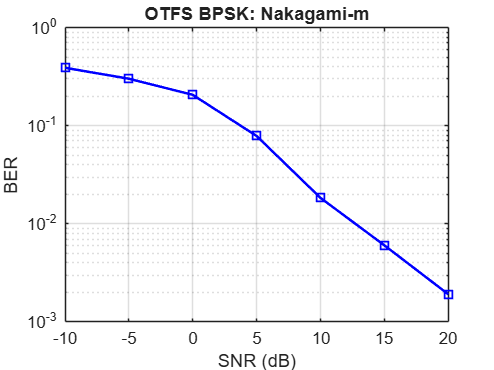


%% ========================================================================
% SIMULATION ENGINE: BER vs SNR
%% ========================================================================
ber_ofdm = zeros(length(snrRange), numCh);
ber_otfs = zeros(length(snrRange), numCh);
pathDelays = [0 2 5]; 
pathGains = [1 0.4 0.2]; 
numTaps = max(pathDelays) + 1;

for s = 1:length(snrRange)
    snr = snrRange(s);
    for f = 1:numFrames
        bits = randi([0 1], numBits, 1);
        syms = qammod(bits, constOrder, 'InputType', 'bit', 'UnitAveragePower', true);
        X_DD = reshape(syms, M, N);
        txOT = transmitOTFS(X_DD, M, N, cpSize);
        txOF = transmitOFDM(X_DD, M, N, cpSize);
        
        for k = 1:numCh
            h = generateExtendedChannel(pathDelays, pathGains, numTaps, channelNames{k});
            % OFDM Processing
            rxOF = awgn(filter(h, 1, txOF), snr, 'measured');
            ber_ofdm(s, k) = ber_ofdm(s, k) + biterr(bits, decodeOFDM(rxOF, fft(h,M), M, N, cpSize, constOrder));
            % OTFS Processing
            rxOT = awgn(filter(h, 1, txOT), snr, 'measured');
            ber_otfs(s, k) = ber_otfs(s, k) + biterr(bits, decodeOTFS(rxOT, fft(h,M), M, N, cpSize, constOrder));
        end
    end
end
ber_ofdm = ber_ofdm / (numBits * numFrames);
ber_otfs = ber_otfs / (numBits * numFrames);

%% ========================================================================
% DOPPLER & EFFICIENCY DATA
% ========================================================================
[b_ot_d, b_of_d] = deal(zeros(length(dopplerRange), 1));
for d = 1:length(dopplerRange)
    fd = dopplerRange(d); err_ot = 0; err_of = 0;
    for f = 1:numFrames
        bits = randi([0 1], numBits, 1);
        syms = qammod(bits, constOrder, 'InputType', 'bit', 'UnitAveragePower', true);
        txOT = transmitOTFS(reshape(syms, M, N), M, N, cpSize); 
        txOF = transmitOFDM(reshape(syms, M, N), M, N, cpSize);
        h = generateExtendedChannel(pathDelays, pathGains, numTaps, 'Rayleigh');
        t = (0:length(txOT)-1)'/fs; shift = exp(1j*2*pi*fd*t);
        rxOT = awgn(filter(h, 1, txOT) .* shift, 15, 'measured');
        rxOF = awgn(filter(h, 1, txOF) .* shift, 15, 'measured');
        err_ot = err_ot + biterr(bits, decodeOTFS(rxOT, fft(h,M), M, N, cpSize, constOrder));
        err_of = err_of + biterr(bits, decodeOFDM(rxOF, fft(h,M), M, N, cpSize, constOrder));
    end
    b_ot_d(d) = err_ot/(numBits * numFrames); 
    b_of_d(d) = err_of/(numBits * numFrames);
end

%% ========================================================================
% FINAL PLOTTING: 16 SEPARATE FIGURES
% ========================================================================

% X-axis ticks for the SNR plots
snrTicks = -10:5:20;

for k = 1:numCh
    % OFDM Figure
    figure('Name', sprintf('Graph %d: OFDM %s', 2*k-1, channelNames{k}));
    semilogy(snrRange, ber_ofdm(:,k), 'r-o', 'LineWidth', 1.5);
    grid on; xlim([-10 20]); 
    xticks(snrTicks); % Force specific points on X-axis
    xlabel('SNR (dB)'); ylabel('BER');
    title(['OFDM BPSK: ', channelNames{k}]);
    
    % OTFS Figure
    figure('Name', sprintf('Graph %d: OTFS %s', 2*k, channelNames{k}));
    semilogy(snrRange, ber_otfs(:,k), 'b-s', 'LineWidth', 1.5);
    grid on; xlim([-10 20]); 
    xticks(snrTicks); % Force specific points on X-axis
    xlabel('SNR (dB)'); ylabel('BER');
    title(['OTFS BPSK: ', channelNames{k}]);
end

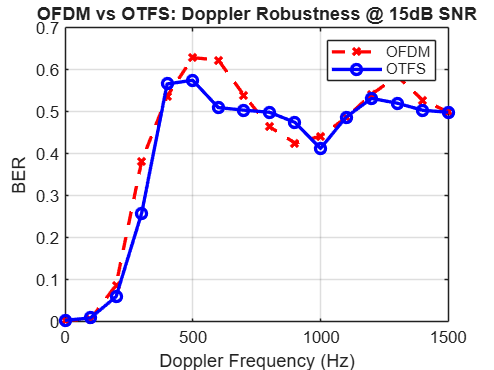


% Figure 15: Doppler Comparison
figure('Name', 'Figure 15: Doppler Comparison BER');
plot(dopplerRange, b_of_d, 'r--x', dopplerRange, b_ot_d, 'b-o', 'LineWidth', 2);
grid on; xlabel('Doppler Frequency (Hz)'); ylabel('BER');
title('OFDM vs OTFS: Doppler Robustness @ 15dB SNR');
legend('OFDM', 'OTFS');

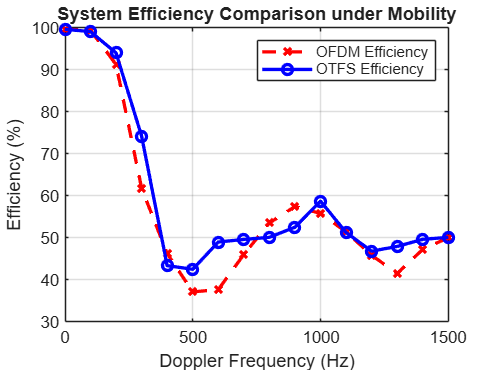


% Figure 16: Efficiency Comparison
figure('Name', 'Figure 16: Efficiency Comparison');
plot(dopplerRange, (1-b_of_d)*100, 'r--x', dopplerRange, (1-b_ot_d)*100, 'b-o', 'LineWidth', 2);
grid on; xlabel('Doppler Frequency (Hz)'); ylabel('Efficiency (%)');
title('System Efficiency Comparison under Mobility');
legend('OFDM Efficiency', 'OTFS Efficiency');

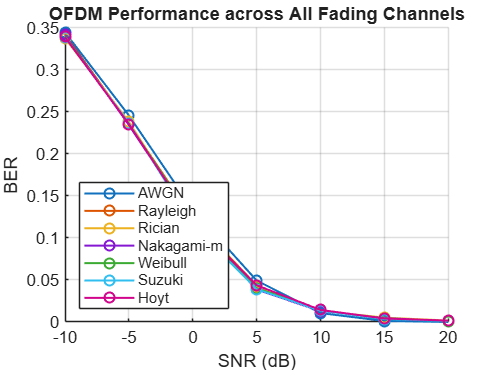


%% ========================================================================
% HELPER FUNCTIONS (UNCHANGED)
% ========================================================================
function h = generateExtendedChannel(delays, gains, taps, type)
    h = zeros(taps, 1);
    g = (randn(length(delays),1)+1j*randn(length(delays),1))/sqrt(2) .* sqrt(gains(:));
    switch type
        case 'AWGN', g = ones(size(g));
        case 'Rician', K = 5; g(1) = sqrt(K/(K+1)) + sqrt(1/(K+1))*g(1);
        case 'Nakagami-m', m = 1.5; g = g .* sqrt(gamrnd(m, 1/m, size(g)));
        case 'Weibull', g = g .* sqrt(wblrnd(1, 2, size(g)));
        case 'Suzuki', sigma_log = 0.5; g = g .* exp(sigma_log * randn(size(g)));
        case 'Hoyt', q = 0.5; g = real(g)*q + 1j*imag(g)*sqrt(2-q^2);
    end
    h(delays+1) = g; h = h/norm(h);
end

function tx = transmitOTFS(X_DD, M, N, cp)
    X_TF = fft(ifft(X_DD, [], 2), [], 1); S = ifft(X_TF, M, 1);
    tx = reshape([S(end-cp+1:end, :); S], [], 1);
end

function tx = transmitOFDM(X_DD, M, N, cp)
    S = ifft(X_DD, M, 1); tx = reshape([S(end-cp+1:end, :); S], [], 1);
end

function bits = decodeOTFS(rx, H, M, N, cp, order)
    rx_mat = reshape(rx(1:(M+cp)*N), M+cp, N);
    Y_TF = fft(rx_mat(cp+1:end, :), M, 1) ./ repmat(H(:), 1, N);
    Y_DD = ifft(fft(Y_TF, [], 2), [], 1); 
    bits = qamdemod(Y_DD(:), order, 'OutputType', 'bit', 'UnitAveragePower', true);
end

function bits = decodeOFDM(rx, H, M, N, cp, order)
    rx_mat = reshape(rx(1:(M+cp)*N), M+cp, N);
    Y_TF = fft(rx_mat(cp+1:end, :), M, 1) ./ repmat(H(:), 1, N);
    bits = qamdemod(Y_TF(:), order, 'OutputType', 'bit', 'UnitAveragePower', true);
end
%% ========================================================================
% ADDITIONAL GRAPHS: CONSOLIDATED CHANNEL COMPARISONS
% ========================================================================

% Figure 17: All OFDM Fading Channels Comparison
figure('Name', 'Figure 17: OFDM - All Channels Comparison');
colors = lines(numCh); % Generate distinct colors
hold on;
for k = 1:numCh
    semilogy(snrRange, ber_ofdm(:,k), 'DisplayName', channelNames{k}, ...
        'Color', colors(k,:), 'Marker', 'o', 'LineWidth', 1.2);
end
hold off;
grid on; xlim([-10 20]); xticks(snrTicks);
xlabel('SNR (dB)'); ylabel('BER');
title('OFDM Performance across All Fading Channels');
legend('Location', 'southwest');

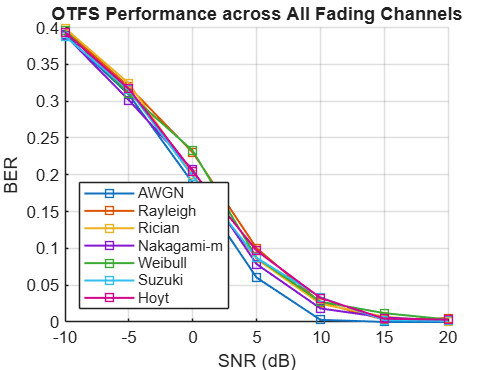


% Figure 18: All OTFS Fading Channels Comparison
figure('Name', 'Figure 18: OTFS - All Channels Comparison');
hold on;
for k = 1:numCh
    semilogy(snrRange, ber_otfs(:,k), 'DisplayName', channelNames{k}, ...
        'Color', colors(k,:), 'Marker', 's', 'LineWidth', 1.2);
end
hold off;
grid on; xlim([-10 20]); xticks(snrTicks);
xlabel('SNR (dB)'); ylabel('BER');
title('OTFS Performance across All Fading Channels');
legend('Location', 'southwest');